clc; close all;

csv_signature = "BEGIN CSV";

all_files = dir('../BluePill-LLC/Data');
most_recent_file = all_files(end-0).name;

file_name = fullfile('../BluePill-LLC/Data', most_recent_file);

% file_name
file_contents = fileread(file_name);

content_begin = regexp(file_contents, csv_signature);
content_end = regexp(file_contents, '\n.*$', 'end');

if isempty(content_begin)
    disp("Did not find CSV signature in file")
end

data = file_contents(content_begin+11:content_end);

FID = fopen('temp.csv', 'w');
fprintf(FID, data);
fclose(FID);

table = readtable('temp.csv', 'Delimiter', ',');

% disp(table.Properties.VariableNames);
% Compute delta t
table.delta_t_ms_ = [NaN; diff(table.Time_ms_)];
% disp(table.Left_PWM(1))

% % Compute Y_Velocity and Y_Target_Velocity
% table.Y_Velocity_cm_s_ = diff(table.Y_Actual_cm_) ./ table.delta_t_ms_(2:end) .* 1000;
% table.Y_Target_Velocity_cm_s_ = diff(table.Y_Target_cm_) ./ table.delta_t_ms_(2:end) .* 1000;

% Compute Left_Actual_deg_ and Right_Actual_deg_
table.Left_Actual_deg_ = 0 - table.Left_Error_deg_;
table.Right_Actual_deg_ = 0 - table.Right_Error_deg_;

% Compute Left_Velocity and Right_Velocity
table.Left_Velocity_deg_s_ = [NaN; diff(table.Left_Actual_deg_) ./ table.delta_t_ms_(2:end) .* 1000];
table.Right_Velocity_deg_s_ = [NaN; diff(table.Right_Actual_deg_) ./ table.delta_t_ms_(2:end) .* 1000];

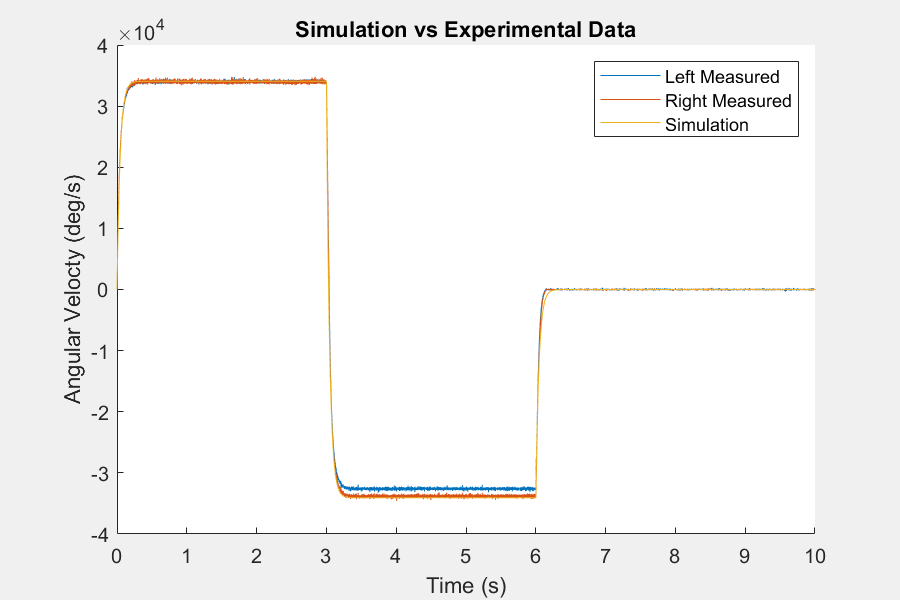

figure;
set(gcf,'visible','on','position',[750 100 600 400]);
hold on
plot(table.Time_ms_ / 1000, -table.Left_Velocity_deg_s_);
plot(table.Time_ms_ / 1000, table.Right_Velocity_deg_s_);


plot(out.simout);
% xlim([0 0.25])
title('Simulation vs Experimental Data');
legend({'Left Measured', 'Right Measured', 'Simulation'});
xlabel("Time (s)");
ylabel("Angular Velocty (deg/s)");

figure
set(gcf, "visible", "on", 'position', [100 100 600 400])

resampledSim = resample(timeseries(out.simout), table.Time_ms_/1000)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [9235x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [9235x1 double]
        DataInfo: 

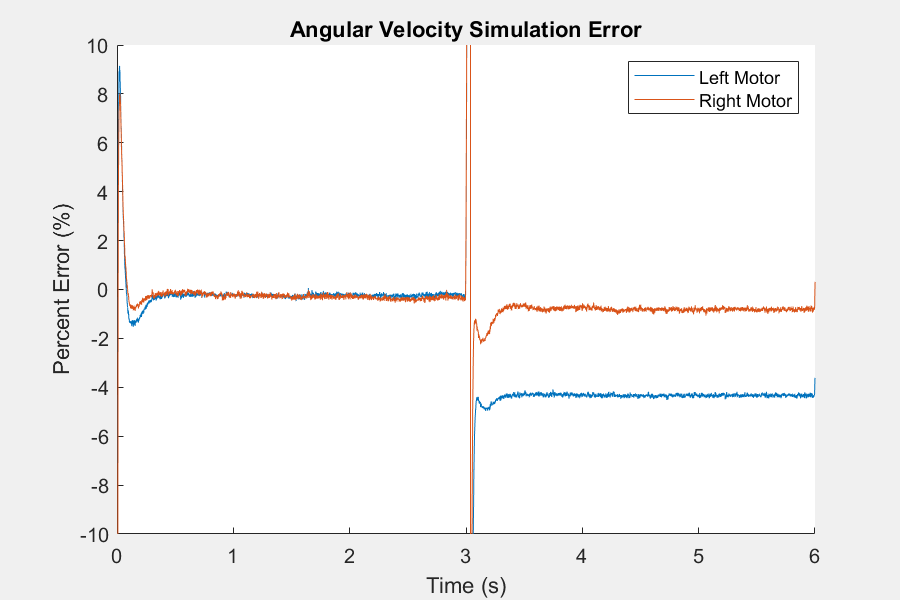

hold on
plot(resampledSim.Time, movmean((-table.Left_Velocity_deg_s_ - resampledSim.Data)./resampledSim.Data, 10)*100)
plot(resampledSim.Time, movmean((table.Right_Velocity_deg_s_ - resampledSim.Data)./resampledSim.Data, 10)*100)
legend({'Left Motor', 'Right Motor'})
xlim([0 6])
ylim([-10 10])
title('Angular Velocity Simulation Error')
xlabel('Time (s)')
ylabel('Percent Error (%)')